%% Set the value of the sensor and vehicle axis
%% NOTE: make sure norm(XYZs) = norm(XYZv) !!!
XYZs = [1.23; 8.77; 4.22];
XYZv = [0;0;sqrt(dot(XYZs,XYZs))];

%% Compute the angle between the two axis using dot product formula
theta = acos(dot(XYZs,XYZv)/(norm(XYZv)^2));

%% Find an axis that is orthogonal to both axis using cross product, normalize
u = cross(XYZs,XYZv);
u = u/norm(u);

%% Compute cross product matrix
ux = [0 -u(3) u(2); u(3) 0 -u(1); -u(2) u(1) 0];

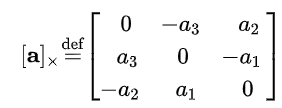

%% Use Axis-Angle method to find the appropriate rotation matrix
R = (cos(theta)*eye(3)) + (sin(theta)*ux) + ((1-cos(theta))*(u*(u')));

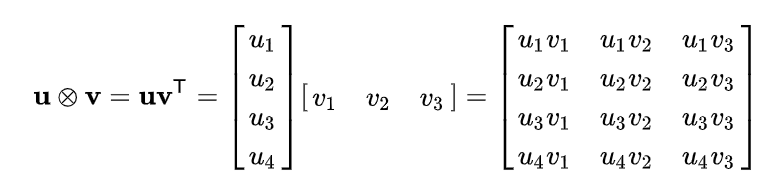

%% Test if the rotation matrix is correct
XYZr = R*XYZs;

error = abs(XYZr - XYZv);